## Preliminary Load Analysis Report 

Objective:

- To model a V-n diagram of an aircraft's manuoever and gust loads 

## V-n diagram 

This diagram helps structural designers plot manoeuvre load envelops, determining critial limit load factors. It is modelled in accordance with [CS-25.335](https://www.easa.europa.eu/en/document-library/easy-access-rules/online-publications/easy-access-rules-large-aeroplanes-cs-25?page=15) certification requirements ensuring optimal safety conditions are met. 

The 2D airfoil aerodynamic properties of the NACA SC(2) 0412 airfoil is determined determined using XFOIL and at reynolds number of 1e7 to model flight conditions at cruise altitudes of 25,000 ft. This is subsequently adjusted to reflect finite-wing effects using a 3-D correction (elliptic efficiency factor $\approx 0\ldotp 9$). Both positive and negative load factors are considered to account for upward and downward aerodynamic loading cases across the flight envelope.

The wings are assumed to not have flaps since it is a hydrogen powered aircraft. 

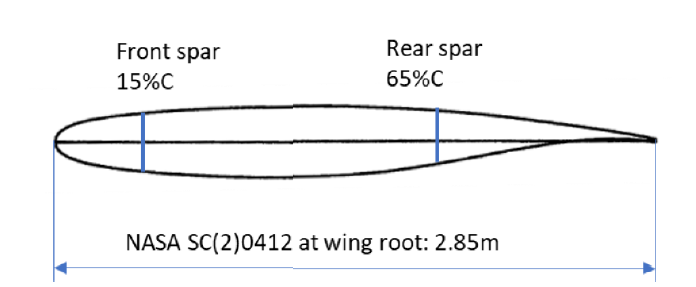

### Parameters for the V-n diagram: 

- Wing loading, W/S = 407 $\textrm{kg}/m^2$ 

- Wing Area $S_{\textrm{ref}}$ -  70.8 $m^{2\;}$

- Take off weight - 28,800 kg  

- Range - 800 nm 

- AR - 14 

- Cruise speed - 325 knots 

- Crusie alt - 25,000 ft altitude 

- dynamic pressure  - 

- density at sea level $\rho_0$- 1.227 kg/m^3 

- density at cruise conditions - 0.5489 kg/m^3

- ${\textrm{Cl}}_{\max \;}$= 1.382525             0.85 xfoil max Cl 

- ${\textrm{Cl}}_{\min \;}$= -1.32   

- $V_{\textrm{EAS}}$  = $V_{\textrm{TAS}} *\sqrt{\left(\frac{\rho }{\rho_0 }\right)}$

- 
$$V_{d\;} =V_{\textrm{EAS}\;} /\;0\ldotp 8$$


- $\textrm{Vc}$ = Cruise speeds in km/hr

On the V-n diagram, the airspeeds are the equivalent airspeeds $\left(V_{\textrm{EAS}} \right)\;$this ensure the structural calculations are more accurate across all altitudes. 

clc; clear; 

% Params 
 
wing_loading = 407; % Wing loading kg/m^2
S = 70.8; % wing area m^2 
mW = 28800; % take off weight kg (mass)
nW = mW * 9.81; % Weight (N)

alt = 25000;    % cruise altitude in ft 
C_alt = alt * 0.3048; % cruise altitude in metres(m) 

rho_inf = 0.5489; % Density of air at cruise conditions in kg/m^3
rho_sl = 1.227; % Density of air at sea level (rho_0) in kg/m^3

cl_max = 2.2; %    % from airfoil, and with knowledge of elliptic wing design#
cl_min = -1.32;     % from airfoil app

v_tas_kts = 325;              % TAS in knots
v_tas_ms  = v_tas_kts * 0.5144;  % convert kt → m/s

% Converting cruise/dive to EAS using density ratio
v_eas_ms  = v_tas_ms * sqrt(rho_inf / rho_sl);
v_d_tas_ms  = v_tas_ms / 0.8;
v_d_eas_ms  = v_d_tas_ms * sqrt(rho_inf / rho_sl);

% Converting to km/h for plotting
v_c = v_eas_ms * 3.6; % km/hr
v_d = v_d_eas_ms * 3.6; % km/hr

% Maneouver Loads specified by CS 25
vEas_km = 0:1:760; % km/hr 
vEas_axis = vEas_km/3.6;

% stall loads
n_pos = 0.5 * rho_sl * S * cl_max .* (vEas_axis).^2 ./ nW; % Calculate positive load factor
n_neg = 0.5 * rho_sl * S * cl_min .* (vEas_axis).^2 ./ nW; % Calculate negative load factor

Include formulars' write them properly before computing to help comparison.

Parameters:

$n_{\max } =2+\;\frac{24000}{W+10000}$        W = maximum take-off weight (MTOW) lb, $n_{\max }$ hould not be less than 2.5 

$n_{\min \;} =-0\ldotp 4\;x\;n_{\max \;}$    should not be less than -1


$${\textrm{Vs}}_1 =\sqrt{\;\frac{2\;W}{\rho_{0\;} S_{\textrm{ref}} {\textrm{Cl}}_{\max } }}$$
 


$$\textrm{Va}=\sqrt{\;\frac{{2\textrm{Wn}}_{\max } }{\rho_{0\;} S_{\textrm{ref}} {\textrm{Cl}}_{\max } }}$$


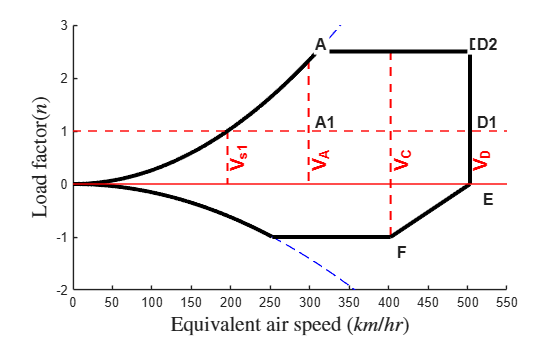

n_max = 2 + (24000 / ((2.2046 * mW) + 10000)); % n_max based on take-off weight, W is in pounds
n_min = -1; % minimum lower manoeuver load
n_1 = 1;
n_25 = 2.5;

v_s = sqrt(2 * nW/(rho_sl * S * cl_max)) * 3.6; % design manueovering speed km/hr

v_a = v_s * sqrt(n_max); % v_a (km/hr)               % rework the v_a, could be wrong
figure; hold on;

plot(vEas_km, n_pos, 'b--', 'LineWidth', 1)
plot(vEas_km, n_neg, 'b--', 'LineWidth', 1)

% Long permines 
% yline(n_max, 'r--', 'LineWidth', 1.5)
% plot([v_a v_d],[n_25 n_25],'LineStyle', '-', 'Color', 'r', 'LineWidth',3)
%yline(n_25, 'r--', 'Linewidth', 1.5)
% yline(n_min, 'r--', 'LineWidth', 1.5)
yline(0, 'r', 'LineWidth', 1.5)
yline(n_1,'r--', 'Linewidth', 1.5)
% yline (n_max*1.5, 'r', 'LineWidth', 1.5) not necessary

% Short lines 
% xline(v_s,'r--', sprintf('v_c = %.1f', v_c), 'LineWidth', 1.5);
% xline(v_d,'r--', sprintf('v_d = %.3f', v_d), 'LineWidth', 1.5)
% xline(v_c,'r--', sprintf('v_c = %.1f', v_c), 'LineWidth', 1.5)
% xline(v_a,'r--', sprintf('v_a = %.1f', v_a), 'LineWidth', 1.5)

plot([v_s v_s], [n_1 0] ,'r--', 'LineWidth', 1.5);
plot([v_d v_d], [n_1 0] ,'r--', 'LineWidth', 1.5);
plot([v_c v_c], [n_25 n_min] ,'r--', 'LineWidth', 1.5);
plot([v_a v_a], [n_max 0] ,'r--', 'LineWidth', 1.5);

% Outlines 
plot([v_a+12 v_d],[n_25 n_25],'k','LineWidth',3)   % here, I changed n_max to n_25
v_neg_lim = sqrt((2*abs(n_min)*nW)/(rho_sl*S*abs(cl_min))) * 3.6;  % km/h
plot([v_neg_lim v_c],[n_min n_min],'k','LineWidth',3)

idxP = vEas_km <= v_a +12.5;
plot(vEas_km(idxP), n_pos(idxP),'k','LineWidth',3)
% 
v_neg_lim = sqrt((2*abs(n_min)*nW)/(rho_sl*S*abs(cl_min))) * 3.6; % km/h

idxN = vEas_km <= v_neg_lim;
plot(vEas_km(idxN), n_neg(idxN),'k','LineWidth',3)
% 
plot([v_d v_d],[0 n_25],'k','LineWidth',3)   % Vd vertical between limits
plot([v_c v_d],[-1 0],'k','LineWidth',3)   % Vd vertical between limits

ylim([-2 3])      % << vertical bounds
xlim([0 550]); 
xticks(0:50:760)    % (optional) horizontal bounds


%  After plotting your envelope and setting xlim/ylim 
ax = gca;
xl = xlim(ax); yl = ylim(ax);

dx = 0.015*diff(xl);   % 1.5% of x-range
dy = 0.03*diff(yl);    % 3% of y-range

% Use governing positive limit for the top line
n_lim = min(n_max, n_25);

% Corner speed (Va) consistent with your envelope
vA = v_s * sqrt(n_lim);

% Some key stations already in your code: v_c, v_d

%  Key points (in data coordinates) 
A  = [vA,  n_lim];
F  = [v_c, n_min];
E  = [v_d, 0];
D  = [v_d, n_lim];
H  = [v_s*sqrt(abs(n_min)), n_min];   % negative stall limit intersection (if you use it)

%  Helper: label point nicely 
labelPt = @(p, str, xoff, yoff) text(p(1)+xoff, p(2)+yoff, str, ...
    'FontWeight','bold', 'FontSize',12, 'Clipping','off', ...
    'BackgroundColor','w', 'Margin',1);

% Point labels 
labelPt(A, 'A',  +dx, +2*dy);
labelPt(D, 'D,', -0.2*dx, +2*dy);
labelPt(E, 'E',  +2*dx, -2*dy);
labelPt(F, 'F',  +dx, -2*dy);

% Optional: H (if you want that corner shown)
% labelPt(H, 'H', +dx, -2*dy);

% "A1 / D1" style labels on reference lines 
% A1: at Va on the n=1 line
labelPt([vA, 1], 'A1', +dx, +dy);

% D1: at Vd on the n=1 line
labelPt([v_d, 1], 'D1', +dx, +dy);

% D2: at Vd on the top line
labelPt([v_d, n_lim], 'D2', +dx, +2*dy);
% Put the labels slightly above the x-axis (n=0 line)
y0 = 0; % x-axis is n=0
yText = y0 + 0.04*diff(yl); % small offset above the axis
dyTick = 0.06*diff(yl); % tick height

% Place labels right under/above those markers
text(v_s, yText, sprintf('V_{s1}'), ...
    'HorizontalAlignment','left', ...
    'VerticalAlignment','top', ...
    'FontWeight','bold','Color','r', ...
    'Rotation', 90, ...
    'Fontsize', 14);

text(v_a, yText, sprintf('V_A'), ...
    'HorizontalAlignment','left', ...
    'VerticalAlignment','top', ...
    'FontWeight','bold','Color','r', ...
    'Rotation', 90, ...
    'Fontsize', 14);


text(v_c, yText, sprintf('V_C'), ...
    'HorizontalAlignment','left', ...
    'VerticalAlignment','top', ...
    'FontWeight','bold','Color','r', ...
    'Rotation', 90, ...
    'Fontsize', 14);

text(v_d, yText, sprintf('V_D'), ...
    'HorizontalAlignment','left', ...
    'VerticalAlignment','top', ...
    'FontWeight','bold','Color','r', ...
    'Rotation', 90, ...
    'Fontsize', 14);

xlabel('Equivalent air speed ($km/hr$)', 'FontSize', 16, 'Interpreter', 'latex');
ylabel('Load factor($n$)', 'FontSize', 16, 'Interpreter', 'latex');
hold off; 

## Gust loads

The gust load factors is modelled in accordance with section [CS-25.341](https://www.easa.europa.eu/en/document-library/easy-access-rules/online-publications/easy-access-rules-large-aeroplanes-cs-25?page=15). The method used considers the absence of a rational analysis and is computed using the equations below: 

- $\mu =\frac{2\;\left(w/s\right)}{\rho \;\textrm{cag}}$           aeroplane mass ratio

- $k_g =\frac{0\ldotp 88}{5\ldotp 3+\mu }$    $\textrm{gust}\;\textrm{alleviation}\;\textrm{factor}\;$(subsonic)

- 
$$n=1\pm \frac{k_g \;\rho_0 {\textrm{Ud}}_e V_a }{2\;\left(W/S\right)}$$


- $C_{\textrm{ref}\;\;\;\approx } \;\frac{2}{3}c_r \frac{1+\lambda +\lambda^{2\;} }{1+\lambda \;}$            $C_{\textrm{ref}} \;$= 2.2488 m        (for a trapezoidal wing) 

- $\lambda =\frac{C_t }{C_r }$ = 0.53

- 
$$\textrm{slope}=0\ldotp 1469\;\textrm{in}\;\textrm{radians}\;\left(a=6\ldotp 125\right)$$


#### Rework this plot for higher reynolds numbers and then find alpha, it should be higher think.

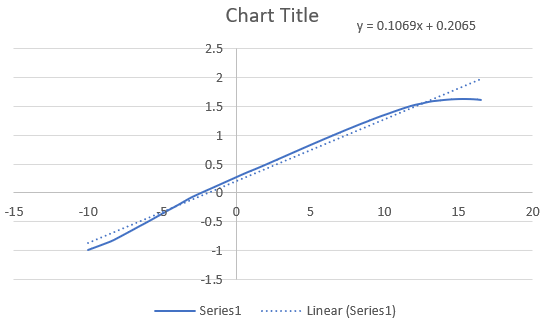

Sine the cruise altitude is above 20,000 ft linear interpolation is used to determine the dive, cruise and max gust speed intensities. The plot below gives a pictural representation of these speeds.

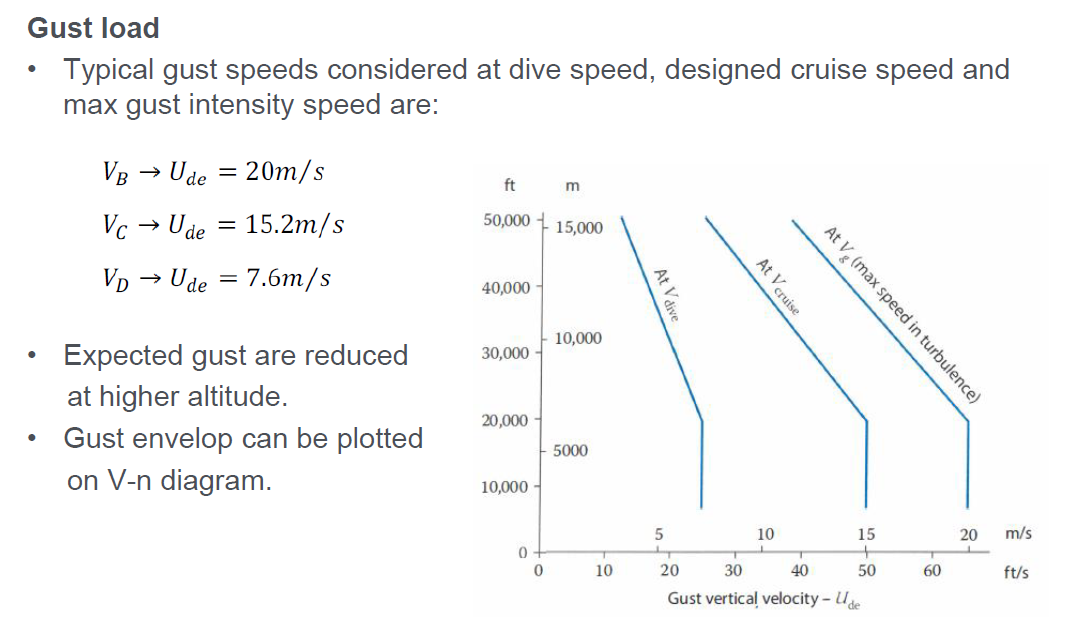

(i) Positive (up) and negative (down) gusts of 50 f.p.s. at VCmust be considered at altitudes between sea level and 20,000 feet. The gust velocity may be reduced linearly from 50 f.p.s. at 20,000 feet to 25 f.p.s. at 50,000 feet. [Ude](chrome-extension://efaidnbmnnnibpcajpcglclefindmkaj/https://www.govinfo.gov/content/pkg/CFR-2011-title14-vol1/pdf/CFR-2011-title14-vol1-sec23-333.pdf)

% Gust lines (drop-in) 

a  = 0.1469 * (180/pi);     % dCL/dalpha [1/rad]
lam = 0.53;                  % taper ratio (NOT aspect ratio)
cr  = 2.85;                  % m
c   = (2/3)*cr * (1 + lam + lam^2)/(1 + lam);   % MAC [m]

mu = (2*(nW/S)) / (rho_inf * 9.81 * c * a);     % mass ratio (dimensionless)
kg = (0.88*mu) /(5.3 + mu);

% Linear interpolation to find Ude

alt_ft = 25000;

U20 = 25;     % fps at 20k
U50 = 12.5;   % fps at 50k

if alt_ft <= 20000
    Ude_fps = U20;
elseif alt_ft >= 50000
    Ude_fps = U50;
else
    Ude_fps_vc = 50 - (alt_ft-20000)/(50000-20000) * (50 - 25);
end

Ude_ms_vc = Ude_fps_vc * 0.3048;

alt_ft = 25000;

U20 = 25;     % fps at 20k
U50 = 12.5;   % fps at 50k

if alt_ft <= 20000
    Ude_fps = U20;
elseif alt_ft >= 50000
    Ude_fps = U50;
else
    Ude_fps_vd = U20 - (alt_ft-20000)/(50000-20000) * (U20-U50);
end

Ude_ms_vd = Ude_fps_vd * 0.3048;

ude_ms_vc = 13.97;              % ude cruise speed m/s
ude_ms_vd = 6.99;               % ude divergence speed m/s

WS = nW/S;                   % N/m^2

dn_vc = (kg * rho_sl * ude_ms_vc .* vEas_axis .* a) ./ (2*WS);
dn_vd = (kg * rho_sl * ude_ms_vd .* vEas_axis .* a) ./ (2*WS);

ng_pos_vc = 1 + dn_vc; ng_neg_vc = 1 - dn_vc;
ng_neg_vd = 1 - dn_vd; ng_pos_vd = 1 + dn_vd;


## Plotting final V-n diagram 

Please, note that the gust envelope outline may be inexact in your case, please take time to ensure your diagram properly outlines the gust envelope.

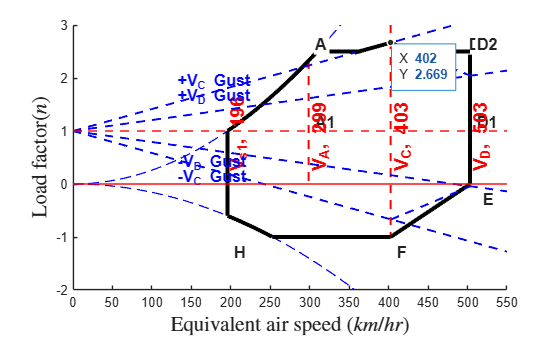

figure; hold on;

plot(vEas_km, n_pos, 'b--', 'LineWidth', 1)
plot(vEas_km, n_neg, 'b--', 'LineWidth', 1)

% Long permines 
% yline(n_max, 'r--', 'LineWidth', 1.5)
% plot([v_a v_d],[n_25 n_25],'LineStyle', '-', 'Color', 'r', 'LineWidth',3)
%yline(n_25, 'r--', 'Linewidth', 1.5)
% yline(n_min, 'r--', 'LineWidth', 1.5)
yline(0, 'r', 'LineWidth', 1.5)

yline(n_1,'r--', 'Linewidth', 1.5)
% yline (n_max*1.5, 'r', 'LineWidth', 1.5) not necessary

% Short lines 
% xline(v_s,'r--', sprintf('v_c = %.1f', v_c), 'LineWidth', 1.5);
% xline(v_d,'r--', sprintf('v_d = %.3f', v_d), 'LineWidth', 1.5)
% xline(v_c,'r--', sprintf('v_c = %.1f', v_c), 'LineWidth', 1.5)
% xline(v_a,'r--', sprintf('v_a = %.1f', v_a), 'LineWidth', 1.5)

plot([v_s v_s], [n_1 -0.6] ,'k', 'LineWidth', 3);
plot([v_d v_d], [n_1 0] ,'r--', 'LineWidth', 1.5);
plot([v_c v_c], [3 n_min] ,'r--', 'LineWidth', 1.5);
plot([v_a v_a], [n_max 0] ,'r--', 'LineWidth', 1.5);

% Outlines 
plot([v_a+12 v_a+65],[n_25 n_25],'k','LineWidth',3)   % here, I changed n_max to n_25

v_neg_lim = sqrt((2*abs(n_min)*nW)/(rho_sl*S*abs(cl_min))) * 3.6;  % km/h

plot([v_neg_lim v_c],[n_min n_min],'k','LineWidth',3)

idxP = (vEas_km >= (v_s)) & (vEas_km <= (v_a+11.5));

plot(vEas_km(idxP), n_pos(idxP),'k','LineWidth',3);

% 
v_neg_lim = sqrt((2*abs(n_min)*nW)/(rho_sl*S*abs(cl_min))) * 3.6; % km/h

idxN = (vEas_km >= (v_s)) & (vEas_km <= (v_neg_lim));
plot(vEas_km(idxN), n_neg(idxN),'k','LineWidth',3)
% 
plot([v_d v_d],[0 n_25],'k','LineWidth',3)   % Vd vertical between limits
plot([v_c v_d],[-1 0],'k','LineWidth',3)   % Vd vertical between limits

ylim([-2 3])      % << vertical bounds
xlim([0 550]); 
xticks(0:50:760)    % (optional) horizontal bounds

%  After plotting your envelope and setting xlim/ylim 
ax = gca;
xl = xlim(ax); yl = ylim(ax);

dx = 0.015*diff(xl);   % 1.5% of x-range
dy = 0.03*diff(yl);    % 3% of y-range

% Use governing positive limit for the top line
n_lim = min(n_max, n_25);

% Corner speed (Va) consistent with your envelope
vA = v_s * sqrt(n_lim);

% Some key stations already in your code: v_c, v_d

% Key points (in data coordinates) 
A  = [vA,  n_lim];
F  = [v_c, n_min];
E  = [v_d, 0];
D  = [v_d, n_lim];
H  = [v_s*sqrt(abs(n_min)), n_min];   % negative stall limit intersection (if you use it)

% Helper: label point
labelPt = @(p, str, xoff, yoff) text(p(1)+xoff, p(2)+yoff, str, ...
    'FontWeight','bold', 'FontSize',12, 'Clipping','off', ...
    'BackgroundColor','w', 'Margin',1);

%  Point labels 
labelPt(A, 'A',  +dx, +2*dy);
labelPt(D, 'D,', -0.2*dx, +2*dy);
labelPt(E, 'E',  +2*dx, -2*dy);
labelPt(F, 'F',  +dx, -2*dy);

% Optional: H (if you want that corner shown)
labelPt(H, 'H', +dx, -2*dy);

% "A1 / D1" style labels on reference lines 
% A1: at Va on the n=1 line
labelPt([vA, 1], 'A1', +dx, +dy);

% D1: at Vd on the n=1 line
labelPt([v_d, 1], 'D1', +dx, +dy);

% D2: at Vd on the top line
labelPt([v_d, n_lim], 'D2', +dx, +2*dy);

% Put the labels slightly above the x-axis (n=0 line)
y0 = 0; % x-axis is n=0

yText = y0 + 0.04*diff(yl); % small offset above the axis

dyTick = 0.06*diff(yl); % tick height

% Place labels right under/above those markers
text(v_s, yText, sprintf('V_{s1}, %.0f',v_s), ...
    'HorizontalAlignment','left', ...
    'VerticalAlignment','top', ...
    'FontWeight','bold','Color','r', ...
    'Rotation', 90, ...
    'Fontsize', 14);

text(v_a, yText, sprintf('V_A, %.0f',v_a), ...
    'HorizontalAlignment','left', ...
    'VerticalAlignment','top', ...
    'FontWeight','bold','Color','r', ...
    'Rotation', 90, ...
    'Fontsize', 14);


text(v_c, yText, sprintf('V_C, %.0f',v_c), ...
    'HorizontalAlignment','left', ...
    'VerticalAlignment','top', ...
    'FontWeight','bold','Color','r', ...
    'Rotation', 90, ...
    'Fontsize', 14);

text(v_d, yText, sprintf('V_D, %.0f',v_d), ...
    'HorizontalAlignment','left', ...
    'VerticalAlignment','top', ...
    'FontWeight','bold','Color','r', ...
    'Rotation', 90, ...
    'Fontsize', 14);


xlabel('Equivalent air speed ($km/hr$)', 'FontSize', 16, 'Interpreter', 'latex');
ylabel('Load factor($n$)', 'FontSize', 16, 'Interpreter', 'latex');

plot(vEas_km, ng_neg_vc, 'LineWidth', 1.5, 'Color', 'b', 'LineStyle','--');
plot(vEas_km, ng_pos_vc, 'LineWidth', 1.5, 'Color', 'b', 'LineStyle','--');
plot(vEas_km, ng_neg_vd, 'LineWidth', 1.5, 'Color', 'b', 'LineStyle','--');
plot(vEas_km, ng_pos_vd, 'LineWidth', 1.5, 'Color', 'b', 'LineStyle','--');
gTop = max(ng_pos_vc, ng_pos_vd);   % upper of the two positive gust lines
n_lim = min(n_max, n_25);           % your top structural limit

% 3) Find indices closest to Vc and Vd 
[~, iD] = min(abs(vEas_km - (v_s-65)));

% Small offset so text doesn't sit exactly on the line
yl = ylim;
dy = 0.03 * (yl(2) - yl(1));

%  4) Labels at Vc 
text(vEas_km(iD), ng_pos_vc(iD) + dy, '+V_C Gust', ...
    'FontWeight','bold','FontSize',12, 'Color','b', ...
    'HorizontalAlignment','left','VerticalAlignment','bottom');

text(vEas_km(iD), ng_neg_vc(iD) - dy, '-V_C Gust', ...
    'FontWeight','bold','FontSize',12, 'Color','b', ...
    'HorizontalAlignment','left','VerticalAlignment','top');

%  5) Labels at Vd 
text(vEas_km(iD), ng_pos_vd(iD) + dy, '+V_D Gust', ...
    'FontWeight','bold','FontSize',12, 'Color','b', ...
    'HorizontalAlignment','left','VerticalAlignment','bottom');

text(vEas_km(iD), ng_neg_vd(iD) - dy, '-V_D Gust', ...
    'FontWeight','bold','FontSize',12, 'Color','b', ...
    'HorizontalAlignment','left','VerticalAlignment','top');


v1 = 357;          % start speed (km/h)

mask = (vEas_km >= v1) & (vEas_km <= v_c);
plot(vEas_km(mask), ng_pos_vc(mask), 'k', 'LineWidth', 3);
plot([402 504],[2.669 2.04],'b--','LineWidth',1.5) 
plot([430 v_d],[n_25 n_25],'k','LineWidth', 3)   % here, I changed n_max to n_25
plot([403 504],[-0.67 -0.04], 'b--', 'Linewidth', 1.5)
plot([402 429.5],[2.669 n_25],'k','LineWidth',3)